# Calculate Equations for Pendulum

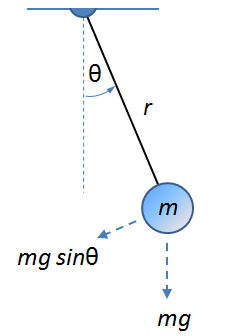

## Define Newton's 2nd law:

Force is equal to *mass * acceleration*:

syms m a
F = m * a

$$F = a\,m$$

Angular acceleration of the pendulum is:


$$a = r\theta''(t)$$


So substituting that into Newton's 2nd law:

syms theta(t) r
F = subs(F, a, r*diff(theta(t),2))

$$F = m\,r\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)$$

And from the diagram above, the tangential force on the pendulum due to gravity is:


$$F = -m g \sin(\theta(t))$$


Therefore,

syms m g a
eqn = F == -m*g*sin(theta(t))

$$eqn = m\,r\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-g\,m\,\sin\left(\theta \left(t\right)\right)$$

And the angular acceleration is:

eqn = eqn/(m*r)

$$eqn = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{g\,\sin\left(\theta \left(t\right)\right)}{r}$$

Solving the equation for an initial position of $1/5$ radians and an initial angular velocity of 0 radians per second yields:

syms Dtheta(t) 
Dtheta(t) = diff(theta(t))

$$Dtheta(t) = \frac{\partial }{\partial t}\theta \left(t\right)$$

sol = dsolve(eqn, theta(0) == 1/5, Dtheta(0) == 0)

sol = [ empty sym ]

The above equation is difficult to solve and does not have a solution that can be expressed with elementary functions. So using the small angle approximation:

eqnSA = subs(eqn, sin(theta(t)), theta(t))

$$eqnSA = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{g\,\theta \left(t\right)}{r}$$

sol = dsolve(eqnSA, theta(0) == 1/5, Dtheta(0) == 0)

$$sol = \frac{{\mathrm{e}}^{\frac{t\,\sqrt{-g\,r}}{r}}}{10}+\frac{{\mathrm{e}}^{-\frac{t\,\sqrt{-g\,r}}{r}}}{10}$$

Now provide the assumptions that $r > 0$ and $g > 0$:

assume(r > 0)
assume (g > 0)
sol = dsolve(eqnSA, theta(0) == 1/5, Dtheta(0) == 0)

$$sol = \frac{\cos\left(\frac{\sqrt{g}\,t}{\sqrt{r}}\right)}{5}$$

Now set the values for gravity, *g*, and the pendulum arm length, *r *:

sol = subs(sol, [g r], [9.81 10])

$$sol = \frac{\cos\left(\frac{\sqrt{10}\,\sqrt{981}\,t}{100}\right)}{5}$$

This provides the solution for the motion of an idealize pendulum. We plot the results below.

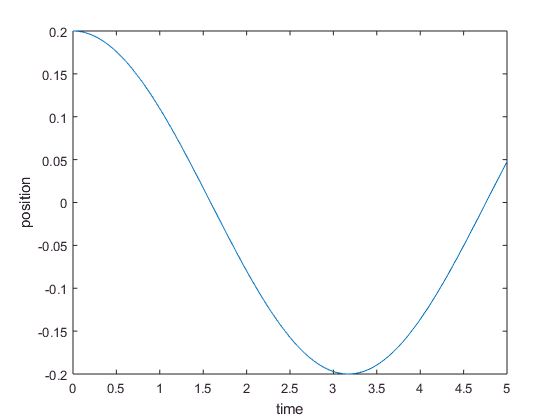

fplot(sol, [0 5])
xlabel('time')
ylabel('position')